# Example 6: Directional vs Robust Color Scaling with Outlier

This example demonstrates the difference between standard and robust scaling methods when colouring the bars based on the difference between pairs of data.

In the first plot the presence of the outlier, pushes all the other bars to the bottom of the colourmap; colouring them with blue. However, in the second plot, the robust scaling is applied, and while the couple with the outlier retains its extreme colour, the other couples colour is not influenced by the presence of the outlier value

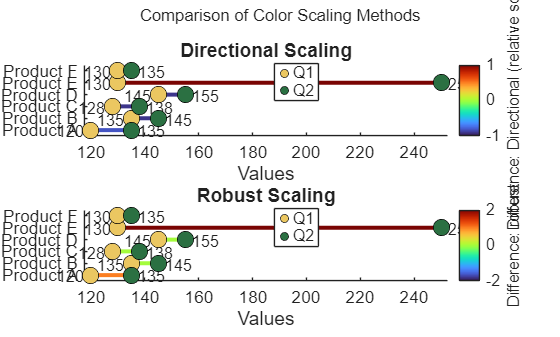

% Demonstrates the difference between standard and robust scaling methods

% Sample data with outlier
products = {'Product A', 'Product B', 'Product C', 'Product D', 'Product E', 'Product F'};
Q1_sales = [120, 135, 128, 145, 130, 130];
Q2_sales = [135, 145, 138, 155, 250, 135]; % Q2 contains an outlier!!! 

figure;

subplot(2, 1, 1);
dumbbellPlot(Q1_sales, Q2_sales,'YLabels', products,'labelX1', 'Q1','labelX2', 'Q2', ...
    'Title', 'Directional Scaling','ColorDist', 'directional','LineWidth', 3);

subplot(2, 1, 2);
dumbbellPlot(Q1_sales, Q2_sales, 'YLabels', products, 'labelX1', 'Q1', ...
    'labelX2', 'Q2','Title', 'Robust Scaling','ColorDist', 'robust', 'LineWidth', 3);

sgtitle('Comparison of Color Scaling Methods')